# Development of Minimisation Function

## Introduction

We now have a function (maxTFromCurrent.m) that for a given input current returns the maximum temperature within the simulation.  The next step is to run this through the optimiser to find the maximum current that we can use yet still stay within the bounds of our maximum permissible temperature.

However, all the optimisation solvers use a minimisation function, not the maximum that we will compute.  Therefore, I like to to a sweep across the parameter space, if possible, and have a look at the surface.  In this case its only one independent variable, so fairly simple.  For higher dimensions, not so.

The steps therefore, are:

- Just explore the parameter space to get a feel for what is happening

- Look for a simple wrapper to convert to a minimisation problem or bound the solution

## Boilerplate

clearvars
kToC = 273.3; % Enable Kelvin to Celcius conversions
tMax = 80; % in Celcius

## Investigate Response to Current

First step here is to look at the response of the simulation to current.

currentToTest = linspace(10, 1000, 20)';
tempFromCurr = zeros(size(currentToTest));
parfor ii = 1:size(tempFromCurr, 1)
    tempFromCurr(ii) = maxTFromCurrent(currentToTest(ii));
end

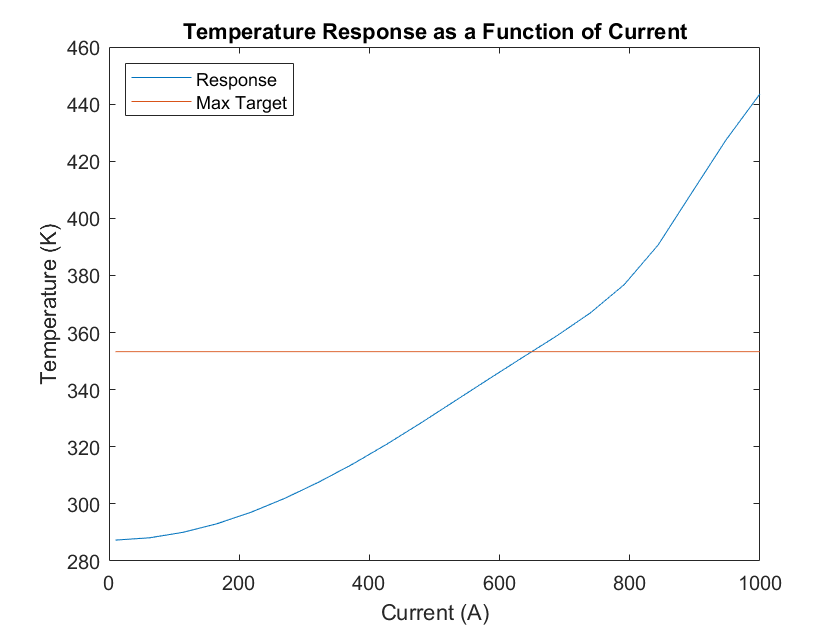

plot(currentToTest, tempFromCurr)
xlabel("Current (A)")
ylabel("Temperature (K)")
title("Temperature Response as a Function of Current")
hold on
plot(currentToTest, (tMax + kToC) * ones(size(currentToTest)))
hold off
legend('Response', 'Max Target', ...
    'Location', "northwest")

## Minimisation Statement

Given the above plot I want to minimise current subject to the following constraints:

- 
$$10\le \textrm{current}\le 1000\;\textrm{Amps}$$


- $\textrm{Temperature}\ge \;$353.3 K

Constraint 1 is to reduce our search space, it is theoretically possible to put kilo-Amps down the cable so lets just assume the current maximises at 1000A.

Constraint 2 on first glance is strange: why keep temperature high?  Remember that this is a *minimisation* problem.  Therefore, the algorithms will simply continue to walk down the response curve until 10A.  This constraint stops that walk.

Copyright © 2020 The MathWorks, Inc.